# RC and  RL Circuits

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

Voltages, currents, instantaneous power, and energy on a capacitor or inductor are discussed when the capacitor or inductor is connected with resistors, sources, and switches. When the capacitor or inductor holds initial energy even there is no input source,  the circuit responds to the initial energy until all the energy is spent. The response of a circuit due to initial energy is called a **natural response** (also **transient response**, **zero input response**, and **source-free response**). In this section, the natural response of RC and RL circuit will be evaluated. 

The response of a RC or  RL  circuit to a dc input signal (step input) is called a **step response**. The step response includes the response due to the initial energy stored in the capacitor or inductor.

## Learning Objectives

- Be able to define the natural and step response of *RL *and *RC *circuits 

- Be able to determine and use the equations for voltage, current, power, and energy in a capacitor, explore how current and voltage vary with time in an RC circuit in the presence of constant voltage with sequential switching.

- Be able to determine and use the equations for voltage, current, power, and energy in a inductor, explore how current and voltage vary with time in an RL circuit in the presence of constant voltage with sequential switching.

- Be able to combine inductors with initial conditions in serial form a single equivalent inductor with an initial condition; be able to combine capacitors with initial conditions in parallel form a single equivalent capacitor with an initial condition.

## Natural Response of RC Circuit 

Consider a series combination of a resistor and an initially charged capacitor, which is given $V(0)=V_0$  at  t=0. 

                    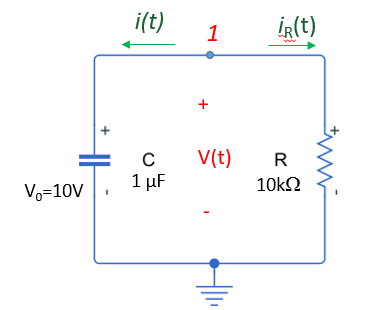       

Given values

u = symunit;

% Given Values in the circuit
R = 10*u.kOhm
C = 1*u.uF
V0 = 10*u.V

For$t\ge 0$, the initial voltage across the capacitor $V\left(0\right)=V_{0\;}$ will introduce current around the circuit. The capacitor will discharge through the resistor. 

Summing the currents at node 1, we have

             
$$i(t)+\frac{v(t)}{R}=0$$
 

The voltage-current relation on the capacitor is

              
$$i(t)=C\frac{dv(t)}{dt}$$
  

Substitution of previous equation 

             
$$C\frac{dv(t)}{dt}+\frac{v(t)}{R}=0$$
         

After solving the equation, the  voltage across the capacitor (and resistor) for $t\ge 0\;$is given by

            
$$v(t)=V(0)e^{-\frac{t}{RC}$$
       

The product of R and C, (RC), is measured in seconds and is called a** time constant**, denoted by 

                
$$\tau=RC$$
    

 Therefore 

            $v(t)=V_0 e^{-\frac{t}{\tau}}, t\geq0$ , 

where $V\left(0\right)=V_{0\;}$ is the voltage across the capacitor at $t=0$.

The voltage v(t) is called **natural response**, **source-free response**, **zero input response (ZIR**), or **transient response**, since it lasts for a brief period of time. 

 Time constant can be calculated as 

tau=R*C

$$tau = 10\,\mathrm{k\Omega}\,\mathrm{\mu F}$$

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{100}\,s$$

Find voltage across the capacitor

syms t;
v=V0*exp(-t/(tau))

$$v = 10\,{\mathrm{e}}^{-100\,t\,\frac{1}{s}}\,V$$

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = 10\,{\mathrm{e}}^{-100\,T}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

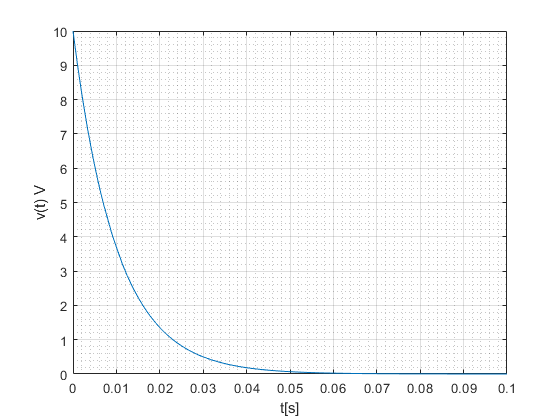

[v_data, units_SI]=separateUnits(v);
fplot(v_data,[0 0.1]) 
xlabel('t[s]')
ylabel(['v(t) ' symunit2str(units_SI)])
grid on
grid minor

The current i(t) through  the capacitor for $t\ge 0$ is given by

        
$$i(t)=C\frac{dv(t)}{dt} =-\frac{V(0)}{R}e^{-\frac{t}{\tau}},  t\ge0$$
   

The current i(t) through  the resistor for $t\ge 0$ is given by

        
$$i_R(t)=\frac{v(t)}{R} =\frac{V(0)}{R}e^{-\frac{t}{\tau}},  t\ge0$$
  

Let's calculate and plot  current i(t)

i_R=v/R

$$i\_R = {\mathrm{e}}^{-100\,T}\,\frac{V}{\mathrm{k\Omega}}$$

i_R=rewrite(i_R,u.mA)

$$i\_R = {\mathrm{e}}^{-100\,T}\,\mathrm{mA}$$

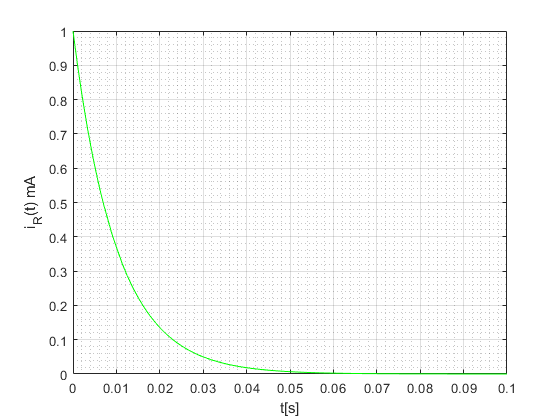


[i_R_data, units_SI]=separateUnits(i_R);
fplot(i_R_data,[0 0.1],'g') 
xlabel('t[s]')
ylabel(['i_R(t) ' symunit2str(units_SI)])
grid on
grid minor

The instantaneous power on the capacitor is given by

            
$$p_C(t)=v(t)i(t)=-\frac{V^2(0)}{R}e^{-\frac{2t}{\tau}},  t\ge0$$


The instantaneous power on the resistor for $t\ge 0\;$ is given by

             
$$p_R(t)=v(t)[i_R(t)]=\frac{V^2(0)}{R}e^{-\frac{2t}{\tau}},  t\ge0$$


Calcuation and ploting the  power on the resistor  for $t\ge 0\;$

pR=v*i_R

$$pR = 10\,{\mathrm{e}}^{-200\,T}\,V\,\mathrm{mA}$$

pR=rewrite(pR,u.mW)

$$pR = 10\,{\mathrm{e}}^{-200\,T}\,\mathrm{mW}$$

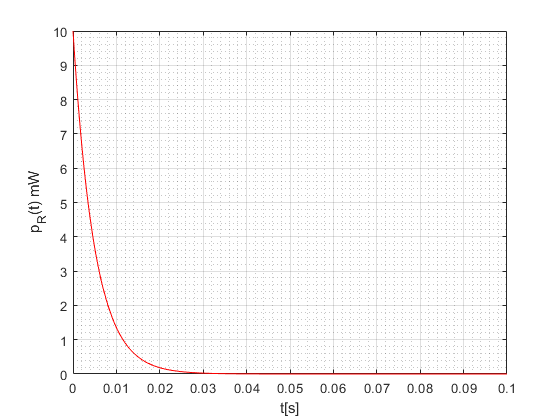


[pR_data, units_SI]=separateUnits(pR);
fplot(pR_data,[0 0.1],'r') 
xlabel('t[s]')
ylabel(['p_R(t) ' symunit2str(units_SI)])
grid on
grid minor

The instantaneous energy on the resistor is given by

             
$$w_R(t)=\int _0^t p_R(\lambda)d\lambda=-\frac{CV^2(0)}{2}\Big (1-e^{-\frac{2t}{\tau}} \Big),  t\ge0$$
  

Circuit can be simulated  in MATLAB Simulink [.](matlab:open('./Simulink\Operational_Amplifier.slx'))[./Simulink\RC.slx](matlab:open('./Simulink\RC.slx'))

            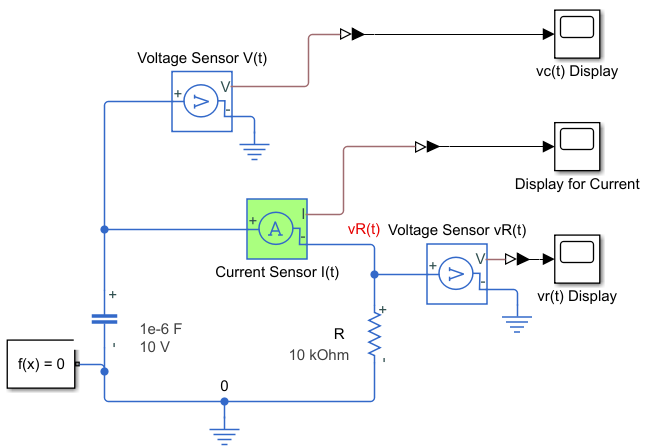

#### Example 1. Natural Response of RC Circuit

Capacitor has been charged  $V_0=8V$before  t = 0. Find the voltage v1(t) across the capacitor, V0(t) across the resistor R3, and the current i(t) through the resistor R2 for t ≥0 and plot v1(t), V0(t)  and i(t) for t ≥0.  Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify our results. 

                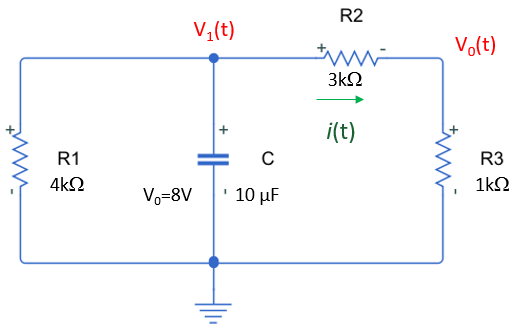

   **Solution**

Given values

u = symunit;

% Given Values in the circuit

R1 = 4*u.kOhm; R2 = 3*u.kOhm; R3 = 1*u.kOhm;
V0 = 8*u.V;    % inital Voltage value
%Let's make C is variable to see the effects
C =7*u.uF % uF 

$$C = 7\,\mathrm{\mu F}$$

To find the equivalent resistance,  the capacitor is treated as an open circuit.  The equivalent resistance  $R_{eq}$ will be  the parallel combination of R1 and R2 +R3. 

             
$$R_{eq}=\frac{R_1(R_2+R_3)}{R_1+R_2+R_3}$$


Req = R1*(R2+R3)/(R1+R2+R3)

$$Req = 2\,\mathrm{k\Omega}$$

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

        
$$\tau =R_{\textrm{eq}} C$$


tau=Req*C

$$tau = 14\,\mathrm{k\Omega}\,\mathrm{\mu F}$$

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{7}{500}\,s$$

The voltage across the capacitor for$\;t\ge 0$  is given by

         
$$v_1(t)=V_0 e^{-\frac{t}{\tau}}, t\geq0$$


syms t;
v1=V0*exp(-t/(tau))

$$v1 = 8\,{\mathrm{e}}^{-\frac{500\,t}{7}\,\frac{1}{s}}\,V$$

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v1 = subs(v1, t, T*u.s)

$$v1 = 8\,{\mathrm{e}}^{-\frac{500\,T}{7}}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

[v1_data, units_SI]=separateUnits(v1);
fplot(v1_data,[0 0.1]) 
xlabel('t[s]')
ylabel([symunit2str(units_SI)])
grid on
grid minor

$v_0(t)$across the resistor R3 can be calculated by $v_0(t)=R_3i(t)$or using voltage  division 

                
$$v_0(t)=\frac{R_3}{R_2+R_3}v_1(t)$$


v0=R3/(R2+R3)*v1

$$v0 = 2\,{\mathrm{e}}^{-\frac{500\,T}{7}}\,V$$

Separate the expression from the units and plot the expression 

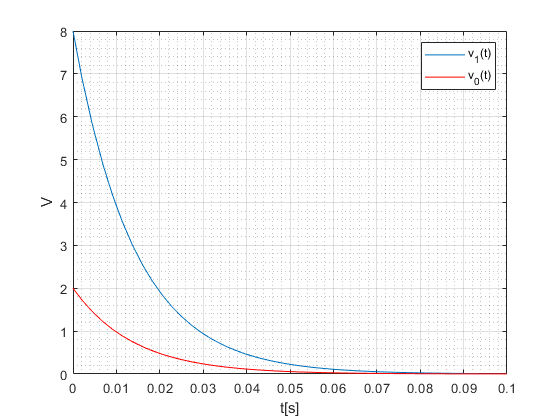

[v0_data, units_SI]=separateUnits(v0);
hold on 
fplot(v0_data,[0 0.1],'r') 

legend ('v_1(t)', 'v_0(t)')

The current i(t) through  the resistor $R_2$ for $t\ge 0$ is given by

            
$$i(t)=\frac{v_1(t)}{R_2+R_3}$$


i=v1/(R2+R3)

$$i = 2\,{\mathrm{e}}^{-\frac{500\,T}{7}}\,\frac{V}{\mathrm{k\Omega}}$$

Convert the time function from $\frac{V}{k\Omega}$ units to $mA$ units, separate the expression from the units, and plot the expression

i=rewrite(i,u.mA)

$$i = 2\,{\mathrm{e}}^{-\frac{500\,T}{7}}\,\mathrm{mA}$$

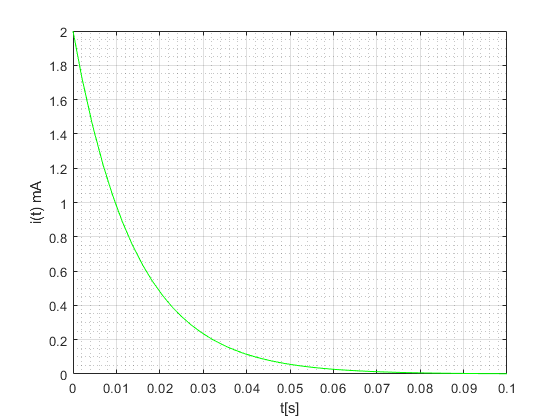

[i_data, units_SI]=separateUnits(i);
figure ()
fplot(i_data,[0 0.1],'g') 
xlabel('t[s]')
ylabel(['i(t) ' symunit2str(units_SI)])
grid on
grid minor

Circuit can be simulated  in MATLAB Simulink  [./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

        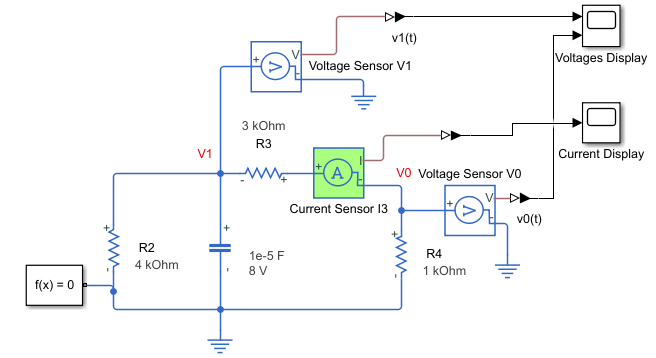

#### Exercise  1. Natural Response of RC Circuit 

Capacitor has been charged $V_0=10V$ before  t = 0. Find the voltage v(t) across the capacitor, $v_1(t)$ across the resistor R5, and the current $i(t)$through the resistor R2 for t ≥0 and plot $v(t)$, $v_1(t)$,  and $i(t)$ for t ≥0.  Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify the results. 

             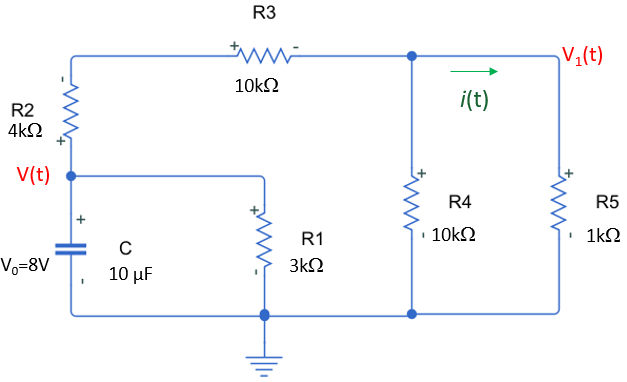           

   **Solution**

Given values

u = symunit;

% Given Values in the circuit

%  R1 = ?? *u.kOhm; ....;
% V0 = ?? *u.V;    % inital Voltage value
% Make C is variable to see the effects
% C =7*u.uF % uF 

Find the equivalent resistance, 

% Req = ??

Find the time constant $\tau \;\;$of the circuit for $t\ge 0$ 

% tau = ??

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{7}{500}\,s$$

Write the voltage across the capacitor for$t\ge 0$    

syms t;
% v=??

 To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = 10\,{\mathrm{e}}^{-100\,T}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

% [v_data, units_SI]=separateUnits(v);
% fplot(v_data,[0 0.1]) 
% xlabel('t[s]')
% ylabel([symunit2str(units_SI)])
% grid on
% grid minor

Find $v_1(t)$ across the resisthor $R_5$ by using voltage  division   

% v1=??
% 
% [v0_data, units_SI]=separateUnits(v0);
% hold on 
% fplot(v0_data,[0 0.1],'r') 
% 
% legend ('v_1(t)', 'v_0(t)')

Find current $i(t)$ through resistor $R_5$  for $t\ge 0$ 

% i=??
% i=rewrite(i,u.mA)
% [i_data, units_SI]=separateUnits(i);
% figure ()
% fplot(i_data,[0 0.1],'g') 
% xlabel('t[s]')
% ylabel(['i(t) ' symunit2str(units_SI)])
% grid on
% grid minor

Simulate the circuit  in MATLAB Simulink 

        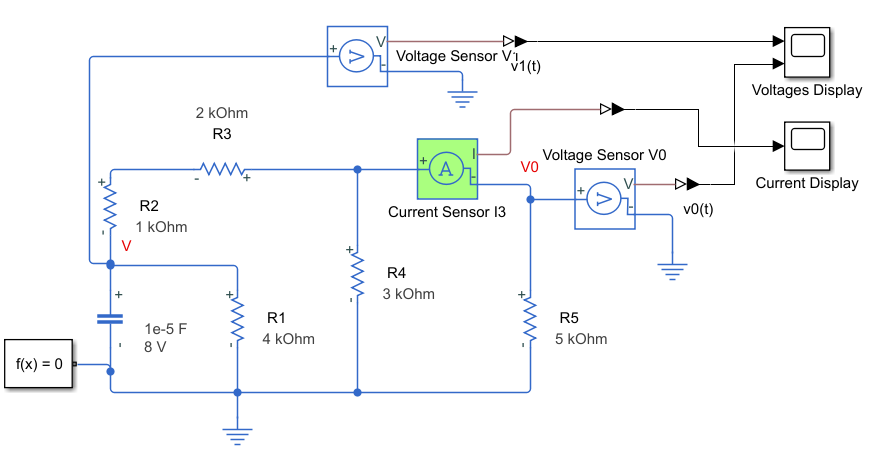

## Natural Response of RL Circuit 

Consider a series combination of a resistor and an initially charged inductor, which is given $I(0)=I_0$  at  t=0. 

                   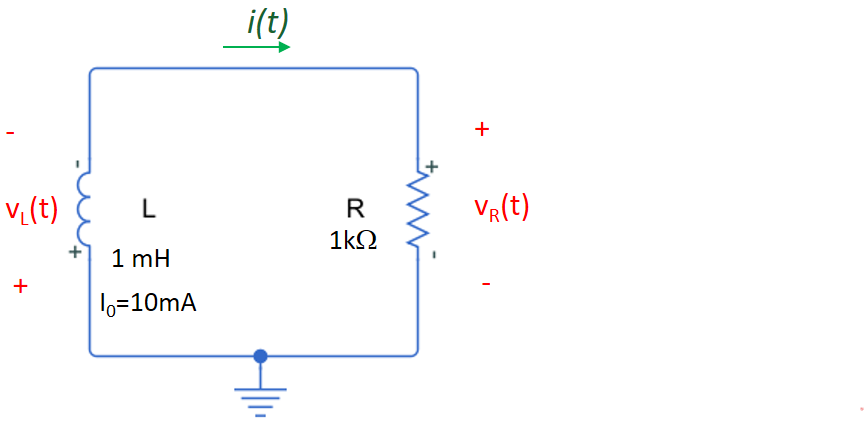

  For$t\ge 0$,  the initial current over the inductor $I(0)=I_0$ starts flowing through the resistor. The inductor will discharge through the resistor. 

Applying KVL $v _ { L }(t) + v _ { R } (t)= 0$

          
$$L \frac { d i(t) } { d t } + R i(t) = 0$$


          
$$\frac { d i (t)} { d t } + \frac { R } { L } i (t)= 0$$


  After solving the equation, the  current  through the inductor (and resistor) for $t\ge 0\;$is given by

       $i ( t ) = I _ { 0 } e ^ { - \frac { R } { L } t }$  or $i ( t ) = I _ { 0 } e ^ { - \frac { 1 } { \tau } t }$ $,t\ge 0$

where $I\left(0\right)=I_{0\;}$ is the current through the inductor at $t=0$. 

The current i(t) is called **natural response**, **source-free response,** **zero input response (ZIR), or transient response**, since it lasts for a brief period of time. Thetime constant  is denoted by 

             
$$\tau=\frac{L}{R}$$


u = symunit;

% Given Values in the circuit
R = 250*u.Ohm;
L = 400*u.mH;
I0 = 10*u.mA;

 Time constant can be calculated as 

tau=L/R

$$tau = \frac{8}{5}\,\frac{\mathrm{mH}}{\Omega }$$

Convert the time function from $\frac{mH}{k\Omega }$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{625}\,s$$

Find current trough the resistance

syms t;
i=I0*exp(-t/(tau))

$$i = 10\,{\mathrm{e}}^{-625\,t\,\frac{1}{s}}\,\mathrm{mA}$$

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
i = subs(i, t, T*u.s)

$$i = 10\,{\mathrm{e}}^{-625\,T}\,\mathrm{mA}$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

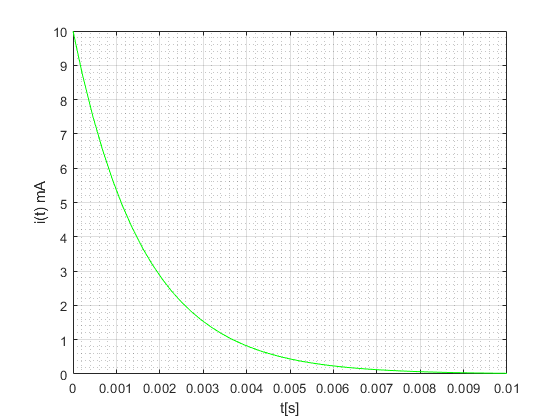

[i_data, units_SI]=separateUnits(i);
fplot(i_data,[0 0.01],'g') 
xlabel('t[s]')
ylabel(['i(t) ' symunit2str(units_SI)])
grid on
grid minor

The voltage $v_L(t)$ across the inductor for  $t\ge 0$ is given by

          
$$v_L(t)=L\frac{di(t)}{dt} =-RI_0^{-\frac{t}{\tau}},  t\ge0$$
         

The voltage $v_R(t)$ across the resistor for  $t\ge 0$ is given by

          
$$v_R(t)=Ri(t) =RI_0^{-\frac{t}{\tau}},  t\ge0$$
   

Let's calculate and plot  voltage $v_R(t)$

v_R=R*i

$$v\_R = 2500\,{\mathrm{e}}^{-625\,T}\,\Omega \,\mathrm{mA}$$

v_R=rewrite(v_R,u.V)

$$v\_R = \frac{5\,{\mathrm{e}}^{-625\,T}}{2}\,V$$

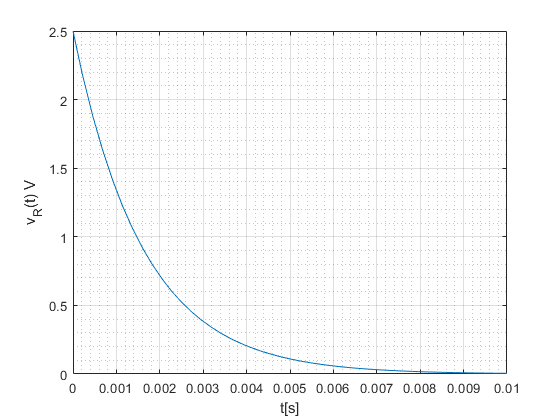


[v_R_data, units_SI]=separateUnits(v_R);
fplot(v_R_data,[0 0.01]) 
xlabel('t[s]')
ylabel(['v_R(t) ' symunit2str(units_SI)])
grid on
grid minor

The instantaneous power on the inductor is given by

            
$$p_L(t)=v_L(t)i(t)=-RI_0^2e^{-\frac{2t}{\tau}},  t\ge0$$


The instantaneous power on the resistor for $t\ge 0\;$ is given by

             
$$p_R(t)=v_R(t)[i(t)]=RI_0^2e^{-\frac{2t}{\tau}},  t\ge0$$


Calcuation and ploting the  power on the resistor  for $t\ge 0\;$

pR=v_R*i

$$pR = 25\,{\mathrm{e}}^{-1250\,T}\,V\,\mathrm{mA}$$

pR=rewrite(pR,u.mW)

$$pR = 25\,{\mathrm{e}}^{-1250\,T}\,\mathrm{mW}$$

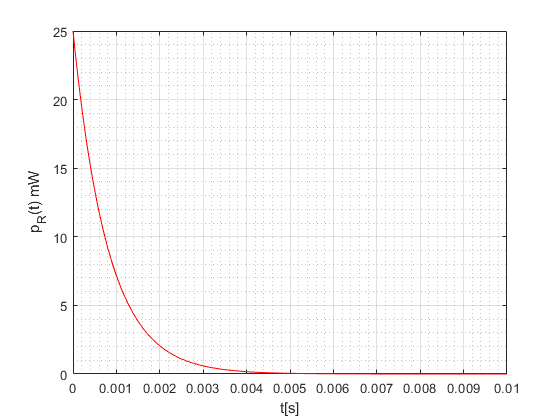


[pR_data, units_SI]=separateUnits(pR);
fplot(pR_data,[0 0.01],'r') 
xlabel('t[s]')
ylabel(['p_R(t) ' symunit2str(units_SI)])
grid on
grid minor

The total energy spent on the resistor is given by

        
$$w_R(t)=\int _0^t p_R(\lambda)d\lambda=\frac{1}{2}LI_0^2\Big (1-e^{-\frac{2t}{\tau}} \Big),  t\ge0$$
   

Circuit can be simulated  in MATLAB Simulink:[./Simulink\RL.slx](matlab:open('./Simulink\RL.slx'))

        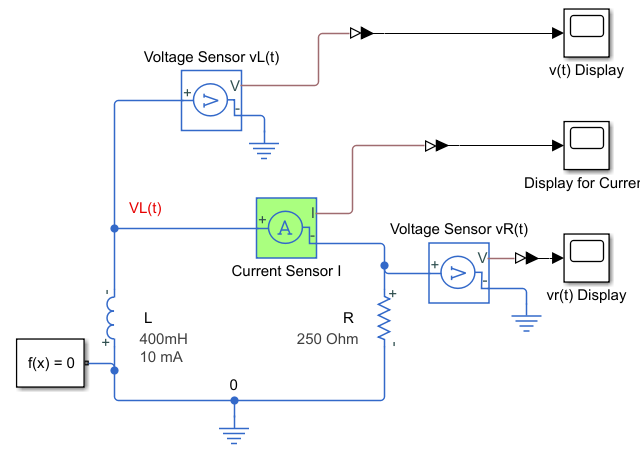

#### Example 1. Natural Response of RL Circuit 

Inductor has been charged  $I_0=12mA$before  t = 0. Find the voltage v(t) across the inductor, $v_1(t)$ across the resistor R1, $v_2(t)$ across the resistor R4, and the current $i_1(t)$ through the resistor R3 and R4 for t ≥0 and plot $v(t),v_1(t),v_2(t)$  and $i_1(t)$for t ≥0.  Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify our results. 

                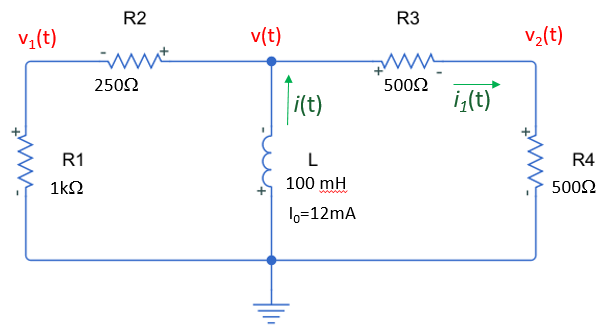

   **Solution**

Given values

u = symunit;

% Given Values in the circuit

R1 = 1*u.kOhm; R2 = 250*u.Ohm; R3 = 500*u.Ohm; R4 = 500*u.Ohm;
I0 = 12*u.mA;    % inital Voltage value
L = 100*u.mH;

To find the equivalent resistance,  the open is treated as an open circuit. Series combination of R1 and R2 are ralalel to  series combination of R3 and R4  to the inductor. The equivalent resistance  Req will be  the parallel combination of R1+R2 and R3 +R4. 

             
$$R_{eq}=\frac{(R_1+R_2)(R_3+R_4)}{R_1+R_2+R_3+R_4}$$


Req = (R1+R2)*(R3+R4)/(R1+R2+R3+R4)

$$Req = \frac{1000\,\left(250\,\Omega +\mathrm{k\Omega}\right)}{1250\,\Omega +\mathrm{k\Omega}}\,\Omega$$

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is given by 

tau=L/Req

$$tau = \frac{1250\,\Omega +\mathrm{k\Omega}}{10\,\left(250\,\Omega +\mathrm{k\Omega}\right)}\,\frac{\mathrm{mH}}{\Omega }$$

Convert the time function from $\frac{mH}{k\Omega }$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{9}{50000}\,s$$

Find the current $i(t)$trough the inductor

syms t;
i=I0*exp(-t/(tau))

$$i = 12\,{\mathrm{e}}^{-\frac{50000\,t}{9}\,\frac{1}{s}}\,\mathrm{mA}$$

The voltage $v_L(t)$ across the inductor for  $t\ge 0$ is given by

          
$$v_L(t)=L\frac{di(t)}{dt} =-R_{eq}I_0^{-\frac{t}{\tau}},  t\ge0$$
    

The voltage $v(t)$ will be equal negative of $v_L(t)$, Therfore 

              
$$v(t)=-v_L(t)=R_{eq}I_0^{-\frac{t}{\tau}},  t\ge0$$


v=Req*I0*exp(-t/(tau))

$$v = \frac{12000\,{\mathrm{e}}^{-\frac{50000\,t}{9}\,\frac{1}{s}}\,\left(250\,\Omega +\mathrm{k\Omega}\right)}{1250\,\Omega +\mathrm{k\Omega}}\,\Omega \,\mathrm{mA}$$

v=rewrite(v,u.V)

$$v = \frac{20\,{\mathrm{e}}^{-\frac{50000\,t}{9}\,\frac{1}{s}}}{3}\,V$$

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = \frac{20\,{\mathrm{e}}^{-\frac{50000\,T}{9}}}{3}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

[v_data, units_SI]=separateUnits(v);
fplot(v_data,[0 0.001]) 
xlabel('t[s]')
ylabel([ symunit2str(units_SI)])
grid on
grid minor

 Using voltage  division, voltage $v_1(t)$ across the R1 for  $t\ge 0$ is given by

          
$$v_1(t)=\frac{R_1}{R_1+R2} v(t)=\frac{R_1}{R_1+R2}R_{eq}I_0^{-\frac{t}{\tau}},  t\ge0$$
              

v1=R1/(R1+R2)*v;

Separate the expression from the units and plot the expression 

[v1_data, units_SI]=separateUnits(v1);
hold on 
fplot(v1_data,[0 0.001],'r') 

Using voltage  division,  voltage $v_2(t)$ across the R4 for  $t\ge 0$ is given by

          
$$v_2(t)=\frac{R_4}{R_3+R4} v(t)=\frac{R_4}{R_3+R4}R_{eq}I_0^{-\frac{t}{\tau}},  t\ge0$$


v2=R4/(R3+R4)*v

$$v2 = \frac{10\,{\mathrm{e}}^{-\frac{50000\,T}{9}}}{3}\,V$$

Separate the expression from the units and plot the expression 

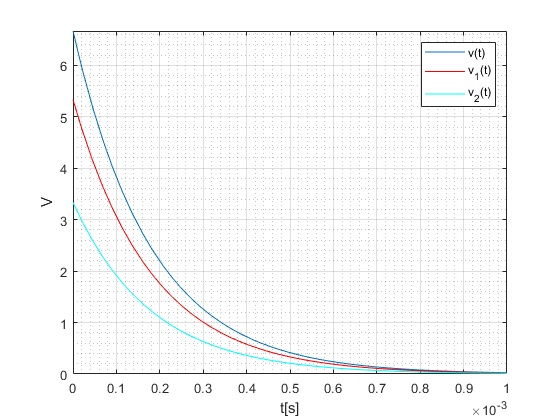

[v2_data, units_SI]=separateUnits(v2);
fplot(v2_data,[0 0.001],'c') 

legend ('v(t)', 'v_1(t)', 'v_2(t)')

The current through Resistor R3 and R4 is given by

            
$$i_1(t)=\frac{v_2(t)}{R_4}$$


i1=v2/R4

$$i1 = \frac{{\mathrm{e}}^{-\frac{50000\,T}{9}}}{150}\,\frac{V}{\Omega }$$

i1=rewrite(i1,u.mA)

$$i1 = \frac{20\,{\mathrm{e}}^{-\frac{50000\,T}{9}}}{3}\,\mathrm{mA}$$

Convert the time function from $\frac{V}{k\Omega}$ units to $mA$ units, separate the expression from the units, and plot the expression

i=rewrite(i,u.mA)

$$i = 12\,{\mathrm{e}}^{-\frac{50000\,t}{9}\,\frac{1}{s}}\,\mathrm{mA}$$

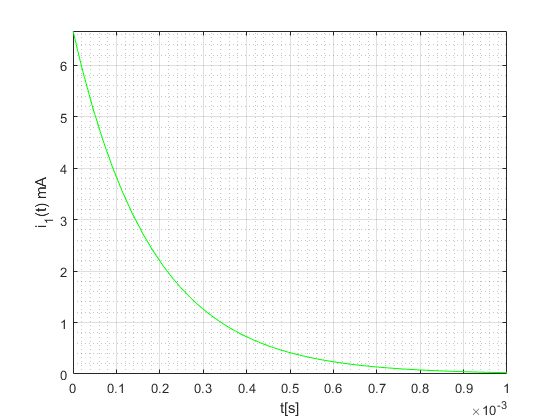

[i1_data, units_SI]=separateUnits(i1);
figure ()
fplot(i1_data,[0 0.001],'g') 
xlabel('t[s]')
ylabel(['i_1(t) ' symunit2str(units_SI)])
grid on
grid minor

Circuit can be simulated  in MATLAB Simulink  [./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

        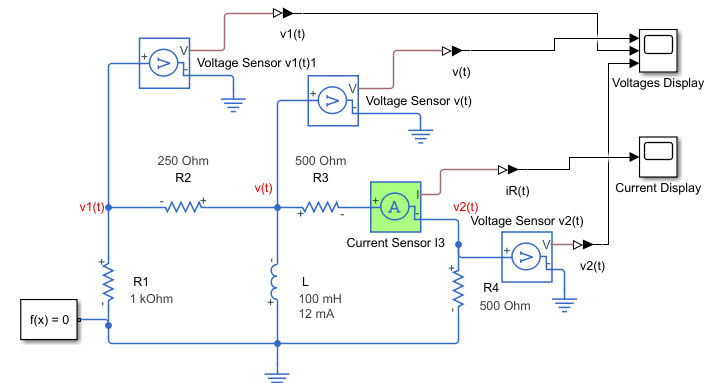

#### Exercise  1. Natural Response of RL Circuit 

Inductor has been charged  $I_0=20mA$before  t = 0. Find the voltage v(t) across the inductor, $v_0(t)$ across the resistor R5, and the current $i(t)$ through the resistor R5  for t ≥0 and plot $v(t),v_0(t)$  and $i_1(t)$for t ≥0.  Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify the results. 

                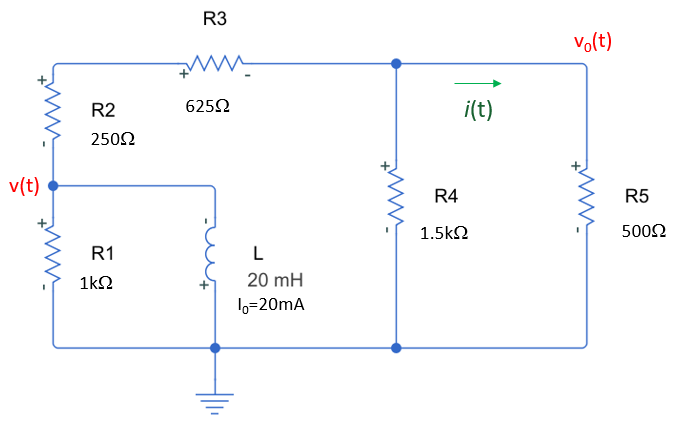

   **Solution**

 Enter given values

% u = symunit;

% Given Values in the circuit

% R1 = ?.kOhm; ...;
% I0 = ??*u.mA;    % inital Voltage value
% L = ??*u.mH;

Find the equivalent resistance,  the open is treated as an open circuit. 

% Req = ?

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is given by 

% tau=?

Convert the time function from $\frac{mH}{k\Omega }$ units to time units.

% tau=rewrite(tau,u.s)

Find current $i_L(t)$trough the inductor

syms t;
% iL=??

Find  voltage $v_L(t)$ across the inductor for  $t\ge 0$ 

The voltage $v(t)$ will be equal negative of $v_L(t)$

% v=??
% v=rewrite(v,u.V)

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

% syms T;
% v = subs(v, t, T*u.s)

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

% [v_data, units_SI]=separateUnits(v);
% fplot(v_data,[0 0.004]) 
% xlabel('t[s]')
% ylabel([ symunit2str(units_SI)])
% grid on
% grid minor

 Using voltage  division, find voltage $v_0(t)$ across the R5 for  $t\ge 0$ 

% v0 = ??

Separate the expression from the units and plot the expression 

% [v0_data, units_SI] = separateUnits(v0);
% hold on 
% fplot(v0_data,[0 0.004],'r') 
% legend ('v(t)', 'v_0(t)')

Find current $i(t)$through Resistor R5 

% i1=??
% i1=rewrite(i1,u.mA)

Convert the time function from $\frac{V}{k\Omega}$ units to $mA$ units, separate the expression from the units, and plot the expression

% i=rewrite(i,u.mA)
% [i1_data, units_SI]=separateUnits(i1);
% figure ()
% fplot(i1_data,[0 0.004],'g') 
% xlabel('t[s]')
% ylabel(['i_1(t) ' symunit2str(units_SI)])
% grid on
% grid minor

Simulate the circuit  in MATLAB Simulink 

        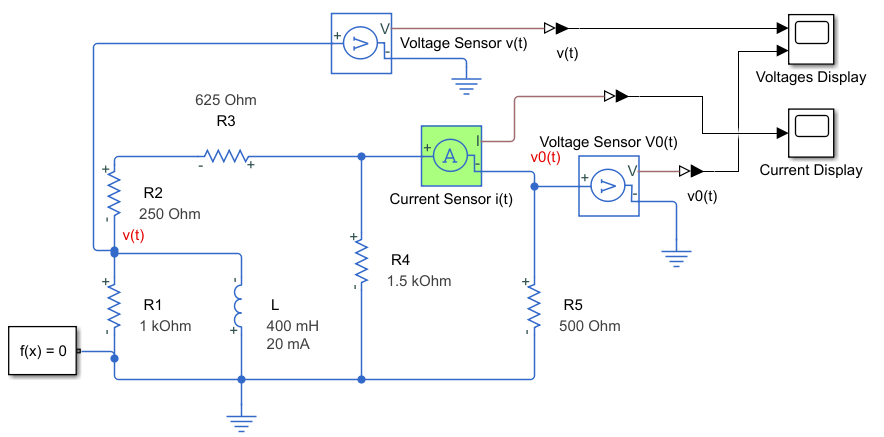

## Step Response of RC Circuit 

The step response of a circuit is its behavior the step function voltage or current source. The switch in the circuit shown in the following circuit  is closed at t = 0. Since the voltage of the capacitor cannot change instantaneously,  the voltage across the capacitor is $V(0)=V_0$ at  t = 0. 

                    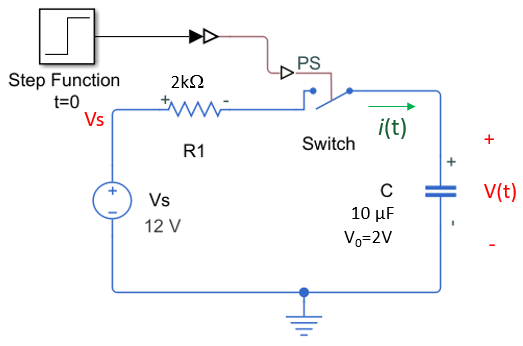

 For $t\geq 0$ , applying KVL

                
$$- V _ { s } + R i ( t ) + v ( t ) = 0$$
               

The current i(t) through the capacitor is given by $i ( t ) = C \frac { d v ( t ) } { d t }$. Substitude the equation

          
$$- V _ { s } + R C \frac { d v ( t ) } { d t } + v ( t ) = 0$$


Dividing by RC  and rearranging

            $\frac { d v ( t ) } { d t } = - \frac { 1 } { R C } [ v ( t ) - V _ { S } ]$   one more step $\frac { d v ( t ) } { v ( t ) - V _ { s } } = - \frac { 1 } { R C } d t$

Taking Integral both sides and simplifying the result. The final solution is given  by

          $v ( t ) = V _ { s } + ( V _ { 0 } - V _ { s } ) e ^ { - \frac { t } { R C } }$ for $t\geq0$.  

At t = 0, the voltage is v(0) = V0, and at $t=\infty$, the voltage is $v(\infty)=V_s$.  The voltage across the capacitor changes from the initial value of $v(0)=V_0$ at t=0 to the final value of $v ( \infty ) = V_s$ at $t = \infty$.

u = symunit;

% Given Values in the circuit
R = 2*u.kOhm;
C = 10*u.uF;
V0 = 2*u.V;
Vs=12*u.V;

The Time constant of the RC circuit is  $\tau=RC$.In more general  $\tau=R_{eq}C$

tau=R*C

$$tau = 20\,\mathrm{k\Omega}\,\mathrm{\mu F}$$

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{50}\,s$$

The **step response** equation can be given as 

          
$$v ( t ) = v ( \infty ) + ( v ( 0 ) - v ( \infty ) ) e ^ { - \frac { t } { \tau } } ,  t \geq 0$$


syms t;
v=Vs+(V0-Vs)*exp(-t/(tau))

$$v = 12\,V-10\,{\mathrm{e}}^{-50\,t\,\frac{1}{s}}\,V$$

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = 12\,V-10\,{\mathrm{e}}^{-50\,T}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

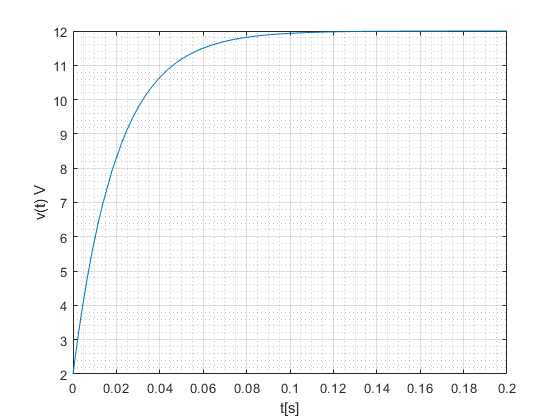

[v_data, units_SI]=separateUnits(v);
fplot(v_data,[0 0.2]) 
xlabel('t[s]')
ylabel(['v(t) ' symunit2str(units_SI)])
grid on
grid minor

If the switch changed position at $t=t_0$

            
$$v ( t ) = v ( \infty ) + ( v ( t _ { 0 } ) - v ( \infty ) ) e ^ { - \frac { (t - t _0)}  { \tau } } , t \geq t _ { 0 }$$


The current $i(t)$ through the capacitor is

            
$$i _( t ) = C \frac { d v ( t ) } { d t } = C \frac { V_s-V_0 } { R C }  e ^ { - \frac { t } { \tau } }=  \frac { V_s-V_0 } { R } e ^ { - \frac { t } { \tau } } , t\ge0$$


i=(Vs-V0)/R*exp(-t/(tau))

$$i = 5\,{\mathrm{e}}^{-50\,t\,\frac{1}{s}}\,\frac{V}{\mathrm{k\Omega}}$$

i=rewrite(i,u.mA)

$$i = 5\,{\mathrm{e}}^{-50\,t\,\frac{1}{s}}\,\mathrm{mA}$$

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
i = subs(i, t, T*u.s)

$$i = 5\,{\mathrm{e}}^{-50\,T}\,\mathrm{mA}$$

Separate the expression from the units by using `separateUnits`. Plot the current i(t) using `fplot`. 

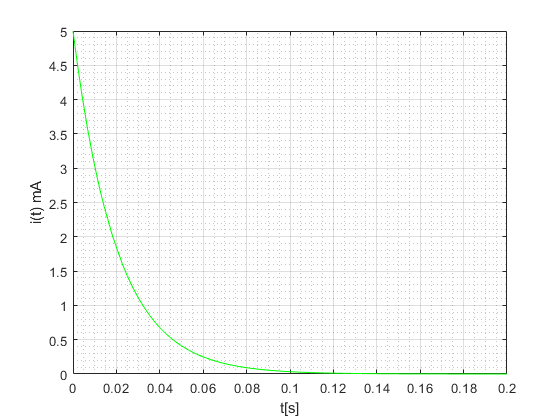

[i_data, units_SI]=separateUnits(i);
fplot(i_data,[0 0.2],'g') 
xlabel('t[s]')
ylabel(['i(t) ' symunit2str(units_SI)])
grid on
grid minor

The instantaneous power on the capacitor is given by

        
$$p_c \left(t\right)=v\left(t\right)i\left(t\right)\;\;\;\;,t\ge 0$$


The instantaneous energy on the capacitor is given by

        
$$w\left(t\right)=\int_0^t p_C \left(\lambda \right)d\lambda \;=\frac{1}{2}{\textrm{Cv}}^2 \left(t\right)\;\;,t\ge 0$$


When computing the step response of circuits, it may help to follow these steps:

- Determine the initial value of the capacitive voltage, 

- Calculate$R_{eq}$ is the equivalent resistance seen from the capacitor.

- Calculate the time constant for the circuit

- Calculate the final value of the variable, which is its value as

Note: 

- $v(0)$is initial voltage across the capacitor at t<=0. If it is not given, it can be calculated from the circuit. If necessary, draw the circuit for t < 0 to evaluate the initial voltage across the capacitor.

- $v(\infty)$is the final value of the voltage across the capacitor at $t=\infty$. The circuit is at steady state at $t=\infty$, the current through the capacitor is zero, and the capacitor can be treated as an open circuit. If necessary, draw the circuit for $t=\infty$ to evaluate the final voltage across the capacitor.

- The time constant is given by $\tau=R_{eq}C$. where $R_{eq}$ is the equivalent resistance seen from the capacitor.  $R_{eq}$ can be found by  deactivating independent source

Circuit can be simulated  in MATLAB Simulink [./Simulink\RC_SR.slx](matlab:open('./Simulink\RC_SR.slx'))

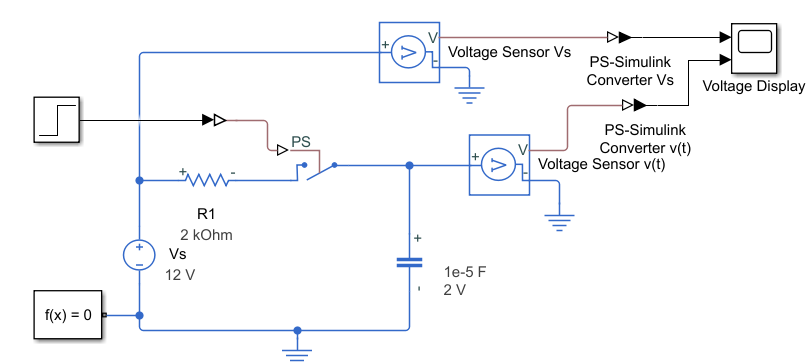

#### Example 3.  Step Response of RC Circuit

In the following circuit, the switch S1 has been open for a long time before it is closed at $t_0=0.02s$ and source Vs2 is a Pulse Voltage source, which has 12V between $0.05s<t<0.15s$.  

- Find the initial voltage V0 across the capacitor at  t = 0.02s

- Find voltage v(t) across the capacitor for $0.02s\leq t \leq 0.05s$ and plot it

- Find voltage v(t) across the capacitor for t = 0.05s

- Find voltage v(t) across the capacitor for $0.05s\leq t \leq 0.15s$ and plot it

- Find voltage v(t) across the capacitor for t = 0.15s 

- Find the voltage v(t) across the capacitor for  ≥ t0.15s and plot it 

 Solve the problem in MATLAB Live Script. Simulate the circuit in Simulink to verify the results.

                 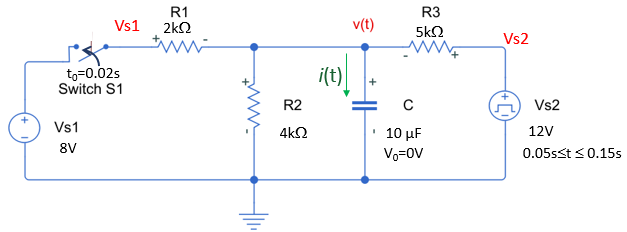 

 **Solution**

Given values

u = symunit;

% Given Values in the circuit
R1 = 2*u.kOhm; R2 = 4*u.kOhm;R3 = 5*u.kOhm;
C = 10*u.uF;
V0 = 0*u.V;
Vs1 = 8*u.V; t0=0.02*u.s;
Vs2 = 12*u.V; t1=0.05*u.s; t2=0.1*u.s;

**Step 1 (**$t \le 0.02s$**)**

The switch S1 has been opened for a long time and source Vs2 has 0V. The voltage v(t) across the capacitor is the initial voltage $V_0=0V$.

                        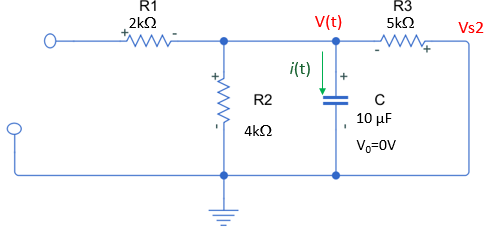

v=V0;
[v_data, units_SI]=separateUnits(v)

$$v\_data = 0$$

$$units\_SI = 1$$

fplot(v_data,[0 0.02],'r') 
xlabel('t[s]')
ylabel(['v(t)' symunit2str(units_SI)])
grid on
grid minor

**Step 2 (**$t_0\le t \le t_1$**) **$0.02s\le t \le 0.05$

The equivalent circuit for $t_0\leq t \leq t_1$ consists of the capacitor with initial voltage $V_{t_0}=V_0$ and resistors R1, R2, source Vs1, parallel R3 since Vs2 is short ($V_{s2}=0V$) as shown in following figure. 

                    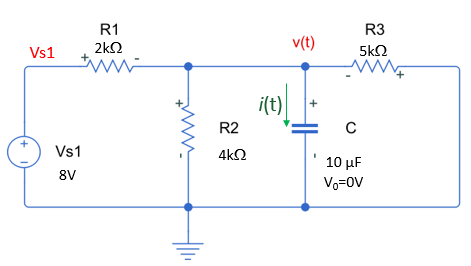

To find the equivalent resistance,  the capacitor is treated as an open circuit.  The equivalent resistance  $R_{eq}$ will be  the parallel combination of R1, R2, and R3. 

             
$$R_{eq}=\frac{1}{\frac{1}{R_1}+\frac{1}{R_2}+\frac{1}{R_3}}$$


Req = 1/(1/R1+1/R2+1/R3)

$$Req = \frac{20}{19}\,\mathrm{k\Omega}$$

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

        
$$\tau =R_{\textrm{eq}} C$$


tau=Req*C

$$tau = \frac{200}{19}\,\mathrm{k\Omega}\,\mathrm{\mu F}$$

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{95}\,s$$

At $t=\infty$, the circuit is in steady state. The current through the capacitor is zero and the capacitor can be treated as an open circuit. Using the voltage divider rule, the final value of v(t) is given by

            
$$v(\infty)=\frac{R_2||R_3}{R_1+(R_2||R_3)}V_{s1}$$


Ra=(R2*R3)/(R2+R3);
Vinf=Ra/(R1+Ra)*Vs1 

$$Vinf = \frac{80}{19}\,V$$

The voltage across the capacitor for $t_0\leq t \leq t_1$   is given by

    
$$v ( t ) = v ( \infty ) + ( v (t_0 ) - v ( \infty ) ) e ^ { - \frac {( t-t_0) } { \tau } } ,  t_0 \leq t \leq t_1$$


     
$$v ( t ) = v ( \infty ) + ( v (t_1) - v ( \infty ) ) e ^ { - \frac {t } { \tau } }e ^ {  \frac {t_0 } { \tau } } ,  t_1 \leq t \leq t1$$


syms t;
v=Vinf+(V0-Vinf)*exp(-(t-t0)/tau)

$$v = \frac{80}{19}\,V-\frac{80\,{\mathrm{e}}^{-95\,\left(t-\frac{1}{50}\,s\right)\,\frac{1}{s}}}{19}\,V$$

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = \frac{80}{19}\,V-\frac{80\,{\mathrm{e}}^{\frac{95\,\left(\frac{1}{50}\,s-T\,s\right)}{s}}}{19}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

[v_data, units_SI]=separateUnits(simplify(v))

$$v\_data = \frac{80}{19}-\frac{80\,{\mathrm{e}}^{-95\,T}\,{\mathrm{e}}^{19/10}}{19}$$

$$units\_SI = V$$

hold on;
fplot(v_data,[0.02 0.05], 'r') 

v(t) at t=0.05 s will be calculated as

 
$$V_{t1}=v (0.05 ) = v ( \infty ) + ( v (t_0) - v ( \infty ) ) e ^ { - \frac {t_1-t_0 } { \tau } }$$


V_t1=Vinf+(V0-Vinf)*exp(-(t1-t0)/tau)

$$V\_t1 = \frac{80}{19}\,V-\frac{80\,{\mathrm{e}}^{-\frac{57}{20}}}{19}\,V$$

This value will be initial value of the capacitor for next period. 

**Step 3 (**$t_1\le t \le t_2$**) **$0.05s\le t \le 0.1$

The equivalent circuit for $t_1\leq t \leq t_2$ consists of the capacitor with initial voltage $V_0=V_{t_1}$ and resistors R1, R2, source Vs1, parallel R3with Vs2  as shown in following figure. 

                    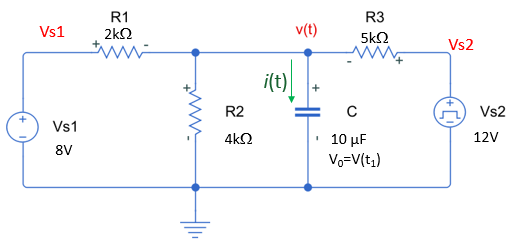

To find the equivalent resistance,  the capacitor is treated as an open circuit and Voltage sources treated as close.   The equivalent resistance  $R_{eq}$ will be  the parallel combination of R1, R2, and R3. 

             
$$R_{eq}=\frac{1}{\frac{1}{R_1}+\frac{1}{R_2}+\frac{1}{R_3}}$$


Req = 1/(1/R1+1/R2+1/R3)

$$Req = \frac{20}{19}\,\mathrm{k\Omega}$$

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

        
$$\tau =R_{\textrm{eq}} C$$


tau=Req*C

$$tau = \frac{200}{19}\,\mathrm{k\Omega}\,\mathrm{\mu F}$$

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{95}\,s$$

At $t=\infty$, the circuit is in steady state. The current through the capacitor is zero and the capacitor can be treated as an open circuit. Using Node equation the final value of v(t) is given by


$$\frac{V_{S1}-v(\infty)}{R_1}-\frac{v(\infty)}{R_2}+\frac{V_{s2}-v(\infty)}{R_3}=-$$


            
$$v(\infty)=\frac{\frac{V_{s1}}{R_1}+\frac{V_{s2}}{R_3}}{\frac{1}{R_1}+\frac{1}{R_2}+\frac{1}{R_3$$


Vinf=(Vs1/R1+Vs2/R3)/(1/R1+1/R2+1/R3) 

$$Vinf = \frac{128}{19}\,V$$

The voltage across the capacitor for $t_0\leq t \leq t_1$  is given by

    
$$v ( t ) = v ( \infty ) + ( v (t_1 ) - v ( \infty ) ) e ^ { - \frac {( t-t_1) } { \tau } } ,  t_1 \leq t \leq t_2$$


syms t;
v=Vinf+(V_t1-Vinf)*exp(-(t-t1)/tau);

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = \frac{128}{19}\,V-{\mathrm{e}}^{\frac{95\,\left(\frac{1}{20}\,s-T\,s\right)}{s}}\,\left(\frac{48}{19}\,V+\frac{80\,{\mathrm{e}}^{-\frac{57}{20}}}{19}\,V\right)$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

[v_data, units_SI]=separateUnits(simplify(v))

$$v\_data = \frac{128}{19}-\frac{16\,{\mathrm{e}}^{\frac{19}{10}-95\,T}\,\left(3\,{\mathrm{e}}^{57/20}+5\right)}{19}$$

$$units\_SI = V$$

hold on;
fplot(v_data,[0.05 0.1], 'r') 

v(t) at t=0.1 s will be calculated as

 
$$V_{t2}=v (0.1s ) = v ( \infty ) + ( v (t_1) - v ( \infty ) ) e ^ { - \frac {t_2-t_1 } { \tau } }$$


V_t2=Vinf+(V_t1-Vinf)*exp(-(t2-t1)/tau)

$$V\_t2 = \frac{128}{19}\,V-{\mathrm{e}}^{-\frac{19}{4}}\,\left(\frac{48}{19}\,V+\frac{80\,{\mathrm{e}}^{-\frac{57}{20}}}{19}\,V\right)$$

This value will be initial value of the capacitor for next period. 

**Step 4 (**$ t \ge t_2$**) **$ t \ge 0.1$

The equivalent circuit for $t \geq t_2$ consists of the capacitor with initial voltage $V_0=V_{t_1}$ and resistors R1, R2, source Vs1, parallel R3 with source Vs2=0V  as shown in following figure. 

                    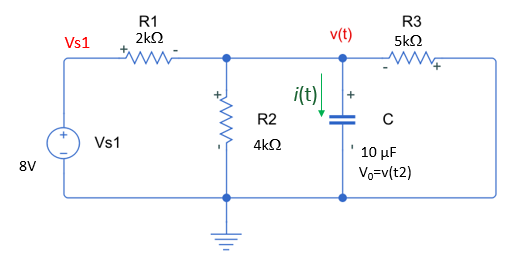

To find the equivalent resistance,  the capacitor is treated as an open circuit and Voltage sources treated as close.   The equivalent resistance  $R_{eq}$ will be  the parallel combination of R1, R2, and R3. 

             
$$R_{eq}=\frac{1}{\frac{1}{R_1}+\frac{1}{R_2}+\frac{1}{R_3}}$$


Req = 1/(1/R1+1/R2+1/R3)

$$Req = \frac{20}{19}\,\mathrm{k\Omega}$$

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

        
$$\tau =R_{\textrm{eq}} C$$


tau=Req*C

$$tau = \frac{200}{19}\,\mathrm{k\Omega}\,\mathrm{\mu F}$$

Convert the time function from $k\Omega \mu F$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{95}\,s$$

At $t=\infty$, the circuit is in steady state. The current through the capacitor is zero and the capacitor can be treated as an open circuit. Using the voltage divider rule, the final value of v(t) is given by

            
$$v(\infty)=\frac{R_2||R_3}{R_1+(R_2||R_3)}V_{s1}$$


Ra=(R2*R3)/(R2+R3);
Vinf=Ra/(R1+Ra)*Vs1 

$$Vinf = \frac{80}{19}\,V$$

The voltage across the capacitor for $t_0\leq t \leq t_1$  is given by

    
$$v ( t ) = v ( \infty ) + ( v (t_2 ) - v ( \infty ) ) e ^ { - \frac {( t-t_2) } { \tau } } ,  t \geq  t_2$$


syms t;
v=Vinf+(V_t2-Vinf)*exp(-(t-t2)/tau);

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = \frac{80}{19}\,V+{\mathrm{e}}^{\frac{95\,\left(\frac{1}{10}\,s-T\,s\right)}{s}}\,\left(\frac{48}{19}\,V-{\mathrm{e}}^{-\frac{19}{4}}\,\left(\frac{48}{19}\,V+\frac{80\,{\mathrm{e}}^{-\frac{57}{20}}}{19}\,V\right)\right)$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

[v_data, units_SI]=separateUnits(simplify(v))

$$v\_data = \frac{80}{19}-\frac{16\,{\mathrm{e}}^{\frac{19}{10}-95\,T}\,\left(3\,{\mathrm{e}}^{57/20}-3\,{\mathrm{e}}^{38/5}+5\right)}{19}$$

$$units\_SI = V$$

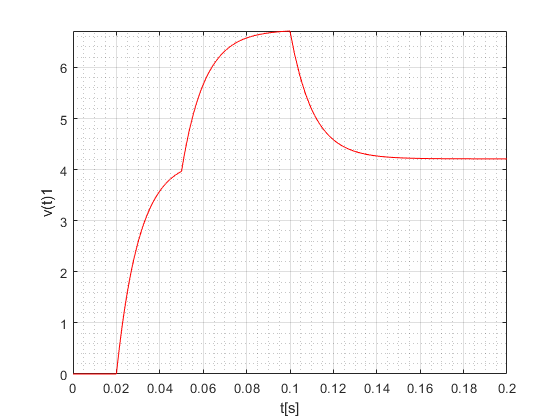

fplot(v_data,[0.1 0.2], 'r') 

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

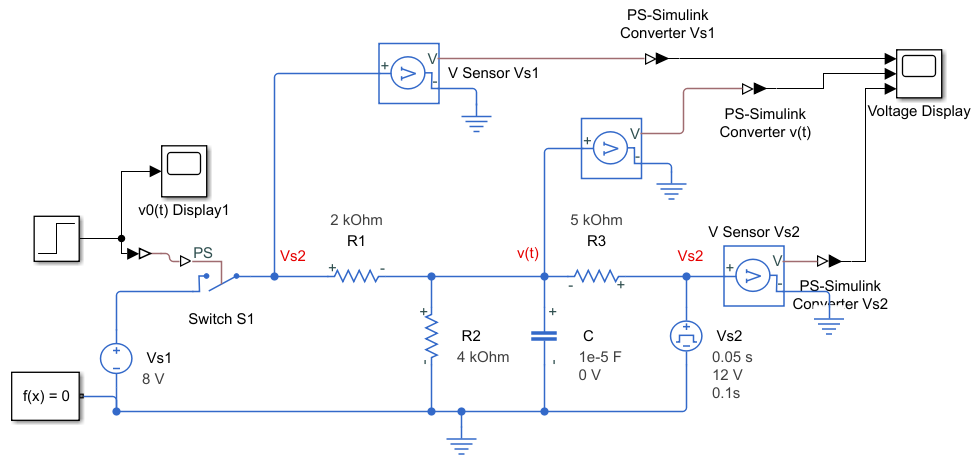

#### Exercise 3: Step Response of RC Circuit

In the following circuit, the switch S1 has been opened for a long time before it is closed at $t_0=0.0s$ and the switch S2 has been closed for a long time before it is opened at $t_0=0.1s$

- Find the initial voltage $V_0$ across the capacitor at  t = 0.0s

- Find voltage v(t) across the capacitor for $0.0 s\leq t \leq 0.1s$ and plot it

- Find voltage v(t) across the capacitor for t = 0.1s

- Find voltage v(t) across the capacitor for $ t \geq 0.1s$ and plot it

 Solve the problem in MATLAB Live Script. Simulate the circuit in Simulink to verify the results.

                  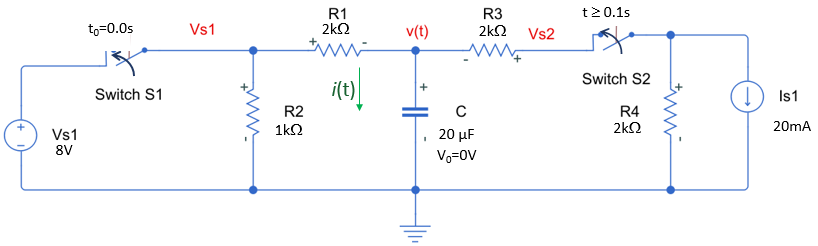

 **Solution**

       Given values

u = symunit;

% Given Values in the circuit
% R1 = ??*u.kOhm; ...;
% C = ??*u.uF;
% V0 = 0*u.V;
% Vs1 = ?*u.V; t0=? *u.s;
% Is1 = ?*u.ma; t1=?*u.s; 

**Step 1 (**$t \le 0.0s$**)**

The switches S1 and S2 has been opened for a long time. Find the initial voltage $V_0=?V$.

% v=V0;
% [v_data, units_SI]=separateUnits(v)
% figure()
% fplot(v_data,[0 0.02],'r') 
% xlabel('t[s]')
% ylabel(['v(t)' symunit2str(units_SI)])
% grid on
% grid minor

**Step 2 (**$t_0\le t \le t_1$**) **$0.0s\le t \le 0.1$

Find the equivalent circuit for $t_0\leq t \leq t_1$ 

Find the equivalent resistance $R_{eq}$,  the capacitor is treated as an open circuit, voltage source is treated as close circuit, current sourse is reated as open circuit   

% Req = ?

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

        
$$\tau =R_{\textrm{eq}} C$$


% tau=Req*C

Convert the time function from $k\Omega \mu F$ units to time units.

% tau=rewrite(tau,u.s)

At $t=\infty$, the circuit is in steady state. The current through the capacitor is zero and the capacitor can be treated as an open circuit. Find the final value of v(t) is given by

% Vinf=??

Find the voltage across the capacitor for $0.0 \leq t \leq 0.1 s$ 

% syms t;
% v=??

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

% syms T;
% v = subs(v, t, T*u.s)

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

% [v_data, units_SI]=separateUnits(v)
% fplot(v_data,[0 0.1],'r') 
% xlabel('t[s]')
% ylabel(['v(t)' symunit2str(units_SI)])
% grid on
% grid minor

Calculate $V(t_1)$ at $t=t_1=0.1s$ 

% V_t1=?

This value will be initial value of the capacitor for next period. 

**Step 3 (**$ t \ge t_1$**) **$t \ge 0.1$

Find the equivalent circuit for $ t \ge t_1$ 

Find the equivalent resistance,  

% Req = ??

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

        
$$\tau =R_{\textrm{eq}} C$$


% tau=Req*C

Convert the time function from $k\Omega \mu F$ units to time units.

% tau=rewrite(tau,u.s)

At $t=\infty$, the circuit is in steady state. The current through the capacitor is zero and the capacitor can be treated as an open circuit. Find the final value of v(t) is given by

% Vinf=?

Find the voltage across the capacitor for $ t \geq t_1$  is given by

% syms t;
% v=? ;

To plot the voltage as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

% syms T;
% v = subs(v, t, T*u.s)

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

% [v_data, units_SI]=separateUnits(v)
% hold on;
% fplot(v_data,[0.1 0.4], 'r') 

Simulate  this exercise using MATLAB Simulink to chek your values. 

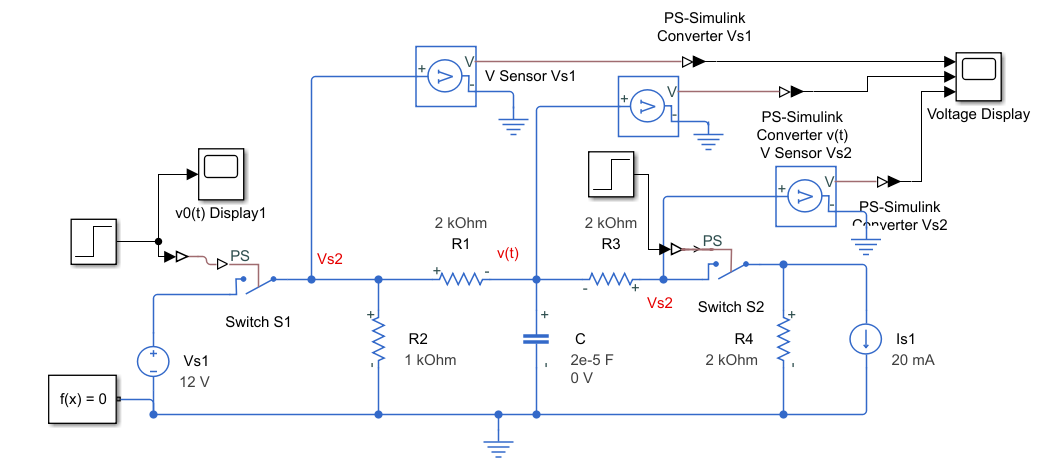

## Step Response of RL Circuit 

The step response of a circuit is its behavior the step function voltage or current source. The switch S in the circuit shown in the following circuit  is closed at $t=0s$. Since the current of the inductor cannot change instantaneously,  the current through the inductor is $I(0)=I_0$ at $t=0s$.  When the switch is closed at $t=0s$, current will start flowing through the inductor. If the inductor is ideal, the resistance value of the inductor is zero current

                    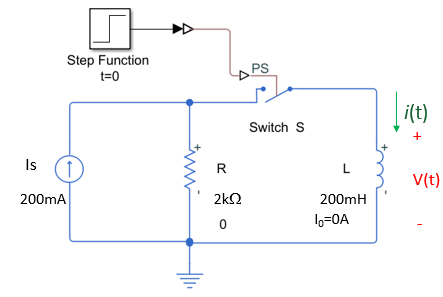

For $t\geq 0$ , applying KCL

                
$$- I _ { s } + \frac{v(t)}{ R}  + i ( t ) = 0$$
               

We know that the voltage v(t) across  the inductor is given by $v ( t ) = L \frac { di ( t ) } { d t }$. Substitude the equation

          
$$- I _ { s } + \frac{L}{R} \frac { d i ( t ) } { d t } + i ( t ) = 0$$


Dividing by L/R  and rearranging

            $\frac { d i( t ) } { d t } = - \frac { R } {L } [ i( t ) - I _ { S } ]$   one more step $\frac { d i ( t ) } { i ( t ) -I _ { s } } = - \frac { R } {  L } d t$

Taking Integral both sides and simplifying the result. The final solution is given  by

          $i ( t ) = I _ { s } + ( I _ { 0 } - I _ { s } ) e ^ { - \frac { L} { R }  t}$ for $t\geq0$.  

This solution is valid for $t\geq0$. The current trough the inductor  from the initial value of $i(0)=I_0$ at t=0 and the final value of $i(\infty)=I_s$ at $t=\infty$ .

u = symunit;

% Given Values in the circuit
R = 2*u.kOhm;
L = 200*u.mH;
I0 = 0*u.mA;
Is=200*u.mA;

The Time constant of the RL circuit is $\tau=\frac{L}{R}$.  More general  $\tau=\frac{L}{R_{eq}}$

tau=L/R;

Convert the time function from $mH/k\Omega$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{10000}\,s$$

The **step response** equation can be given as 

          
$$i ( t ) = i ( \infty ) + ( i ( 0 ) - i ( \infty ) ) e ^ { - \frac { t } { \tau } } ,  t \geq 0$$


syms t;
i=Is+(I0-Is)*exp(-t/(tau))

$$i = 200\,\mathrm{mA}-200\,{\mathrm{e}}^{-10000\,t\,\frac{1}{s}}\,\mathrm{mA}$$

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
i = subs(i, t, T*u.s)

$$i = 200\,\mathrm{mA}-200\,{\mathrm{e}}^{-10000\,T}\,\mathrm{mA}$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

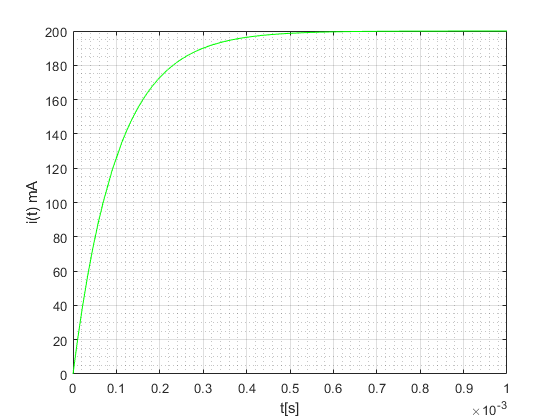

[i_data, units_SI]=separateUnits(i);
figure ();
fplot(i_data,[0 0.001],'g') 
xlabel('t[s]')
ylabel(['i(t) ' symunit2str(units_SI)])
grid on
grid minor

If the switch changed position at t=t0

            
$$i ( t ) = i ( \infty ) + ( i ( t _ { 0 } ) - i ( \infty ) ) e ^ { - \frac { t - t _ { 0 } } { \tau } } , t > t _ { 0 }$$


The voltage v(t) across  the inductor 

            
$$v( t ) = L \frac { d i ( t ) } { d t } = L(i(0)-i( \infty ))(- \frac {R } { L }) e ^ { - \frac { R } { L }t }= - ( I _ { 0 } -i( \infty ) )Re ^ { - \frac {R } { L } t} u ( t )$$


v=-(I0-Is)*R*exp(-t/(tau))

$$v = 400\,{\mathrm{e}}^{-10000\,t\,\frac{1}{s}}\,\mathrm{k\Omega}\,\mathrm{mA}$$

v=rewrite(v,u.V)

$$v = 400\,{\mathrm{e}}^{-10000\,t\,\frac{1}{s}}\,V$$

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
v = subs(v, t, T*u.s)

$$v = 400\,{\mathrm{e}}^{-10000\,T}\,V$$

Separate the expression from the units by using `separateUnits`. Plot the current i(t) using `fplot`. 

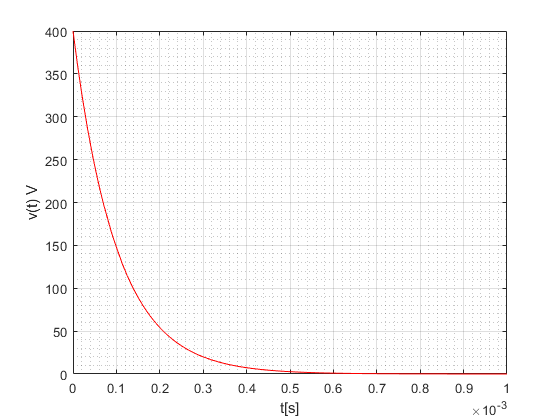

[v_data, units_SI]=separateUnits(v);
figure ();
fplot(v_data,[0 0.001],'r') 
xlabel('t[s]')
ylabel(['v(t) ' symunit2str(units_SI)])
grid on
grid minor

The instantaneous power on the onductor is given by

        
$$p_c \left(t\right)=v\left(t\right)i\left(t\right)\;\;\;\;,t\ge 0$$


The instantaneous energy on the inductor is given by

        
$$w\left(t\right)=\int_0^t p_C \left(\lambda \right)d\lambda \;=\frac{1}{2}{\textrm{Li}}^2 \left(t\right)\;\;,t\ge 0$$


The current iR(t) through the resistor R is given by

        
$$i_R(t)=\frac{V(t)}{R}=-(i(0)-i(\infty)e^{-\frac{t}{\tau}} $$


When computing the step response of circuits, it may help to follow these steps:

- Determine the initial value of the Inductor current, 

- Calculate$R_{eq}$ is the equivalent resistance seen from the inductor.

- Calculate the time constant for the circuit

- Calculate the final current value of the inductor, which is its value as $t=\infty$

Note: 

- $i(0)$is initial current through the inductor at t<=0. If it is not given, it can be calculated from the circuit. If necessary, draw the circuit for t < 0 to evaluate the initial current through the inductor.

- $i(\infty)$is the final value of the current through the inductor at $t=\infty$. The circuit is at steady state at $t=\infty$, the voltage across the inductor is zero, and the capacitor can be treated as an short circuit. If necessary, draw the circuit for $t=\infty$ to evaluate the final current through the inductor.

- The time constant is given by $\tau=\frac{L}{R_{eq}$, where $R_{eq}$ is the equivalent resistance seen from the inductor.  $R_{eq}$ can be found by  deactivating independent sources

    Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

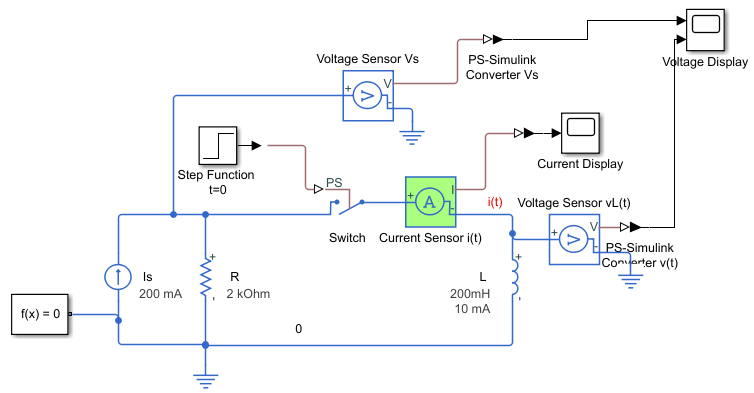

#### Example 4. Step Response of RL Circuit

In the following circuit, the switches S1 and S2 has been opened for a long time before it is closed at $t_0=0.0s$ 

- Find the initial current $I_0$ through the inducthor at  t = 0.0s

- After switch is opened, find the equivalent resistance seen from the inductor.

- Find the time constant $\tau$.

- Find current $i(t)$ through the inductor for $ t \ge 0$ and plot $i(t)$for $ t \ge 0$

 Solve the problem in MATLAB Live Script. Simulate the circuit in Simulink to verify the results.

                 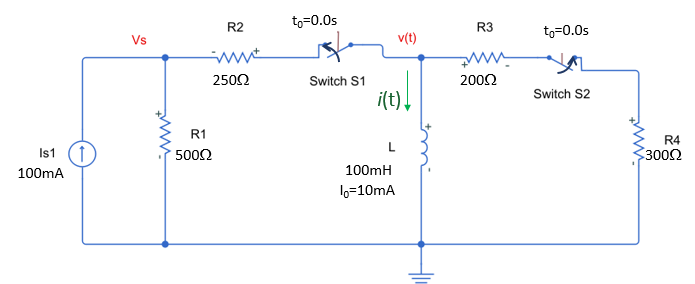

Given values

u = symunit;

% Given Values in the circuit
R1 = 500*u.Ohm; R2 = 250*u.Ohm; R3 = 200*u.Ohm; R4 = 300*u.Ohm;
L = 100*u.mH; I0 = 10*u.mA;
Is = 100*u.mA; t0=0.0*u.s;

**Step 1 (**$t \le 0.0s$**)**

the switches S1 and S2 has been opened for a long time and the current through the inductor is the initial current $I_0=10mA$.

**Step 2 (**$ t \ge 0$**) **

The equivalent circuit for $t \geq 0$ consists of the indutor with initial current $i(0)=I_0$ and resistors R1, R2, R3, and R4.

To find the equivalent resistance,  the inductor is treated as an open circuit.  The equivalent resistance  $R_{eq}$ will be  the parallel combination of R1+R2  and R3+R4. 

             
$$R_{eq}=\frac{(R_1+R_2)(R_3+R_4)}{R_1+R_2+R_3+R_4$$


Req = (R1+R2)*(R3+R4)/(R1+R2+R3+R4)

$$Req = 300\,\Omega$$

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

       
$$\tau=L/R_{eq}$$


tau=L/Req

$$tau = \frac{1}{3}\,\frac{\mathrm{mH}}{\Omega }$$

Convert the time function from $mH /k\Omega$ units to time units.

tau=rewrite(tau,u.s)

$$tau = \frac{1}{3000}\,s$$

At $t=\infty$, the circuit is in steady state. The voltage cross  the inductor is zero and the inductor can be treated as an short circuit. Using the current divider rule, the final value of $i(\infty)$ is given by

            
$$i(\infty)=\frac{R_1}{R_1+R_2}I_S$$


Iinf=R1/(R1+R2)*Is

$$Iinf = \frac{200}{3}\,\mathrm{mA}$$

The **step response** equation can be given as 

          
$$i ( t ) = i ( \infty ) + ( i ( 0 ) - i ( \infty ) ) e ^ { - \frac { t } { \tau } } ,  t \geq 0$$


syms t;
i=Iinf+(I0-Iinf)*exp(-t/(tau))

$$i = \frac{200}{3}\,\mathrm{mA}-\frac{170\,{\mathrm{e}}^{-3000\,t\,\frac{1}{s}}}{3}\,\mathrm{mA}$$

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

syms T;
i = subs(i, t, T*u.s)

$$i = \frac{200}{3}\,\mathrm{mA}-\frac{170\,{\mathrm{e}}^{-3000\,T}}{3}\,\mathrm{mA}$$

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

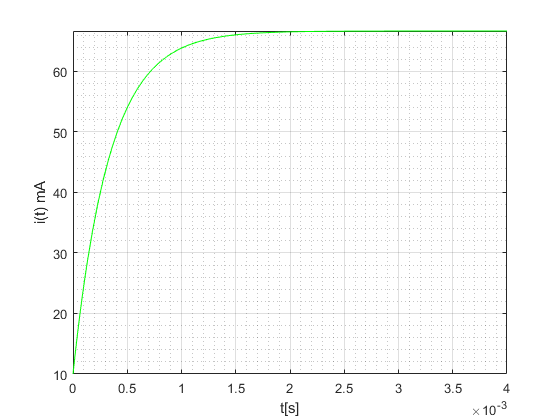

[i_data, units_SI]=separateUnits(i);
figure ();
fplot(i_data,[0 0.004],'g') 
xlabel('t[s]')
ylabel(['i(t) ' symunit2str(units_SI)])
grid on
grid minor

 Circuit can be simulated  in MATLAB Simulink[./Simulink\Example_4.slx](matlab:open('./Simulink\Example_4.slx'))

### 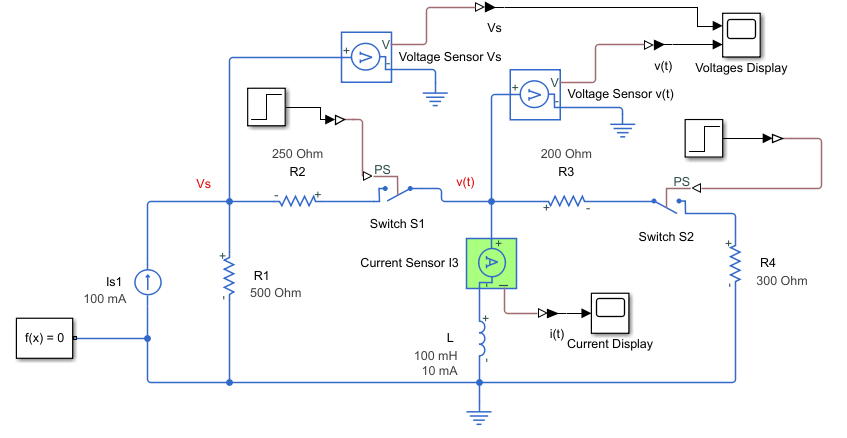

#### Exercise 4.  Step Response of RL Circuit

In the following circuit, the switches S1  has been opened for a long time before it is closed at $t_0=0.005s$ 

Step 1 ($0\leq t \le 0.05s$)

- Find the initial current $I_0$ through the inductor  at  t = 0.0s

- Find the final current $i(\infty)$ through the inductor  at  $t=\infty$

- Find the resistance seen from the inductor .

- Find the time constant $\tau$.

- Find current $i(t)$ through the inductor for $0\leq t \le 0.05s$ and plot $i(t)$for $ t \ge 0$

- Find the initial current $I_0$ through the inducthor at  t = 0.005s for next step

Step 1 ($t \ge 0.05s$)

- Find the final current $i(\infty)$ through the inductor  at  $t=\infty$

- Find the resistance seen from the inductor.

- Find the time constant $\tau$.

- Find current $i(t)$ through the inductor for $t \ge 0.05s$ and plot $i(t)$for $ t \ge 0$

 Solve the problem in MATLAB Live Script. Simulate the circuit in Simulink to verify the results.

                      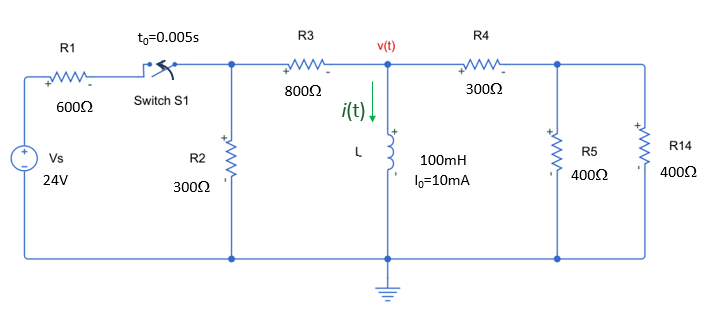

   **Solution:**      

Given values

% u = symunit;
% 
% % Given Values in the circuit
% R1 = ?? *u.Ohm; R2 =....
% L = ??*u.mH; I0 = ??*u.mA;
% Vs = ??*u.V; t0=0.005*u.s;

**Step 1 **($0\leq t \le 0.05s$)

The switches S1 has been opened for a long time and the initial current $I_0$.

At $t=\infty$, the circuit is in steady state. The voltage cross  the inductor is zero and the inductor can be treated as an short circuit. Find the final current $i(\infty)$ through the inducthor at  $t=\infty$

% Iinf=?

Find the equivalent resistance,  the inductor is treated as an open circuit.  

% Req = ?

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

       
$$\tau=L/R_{eq}$$


% tau=L/Req

Convert the time function from $mH /k\Omega$ units to time units.

% tau=rewrite(tau,u.s)

Find current $i(t)$ through the inductor for $0\leq t \le 0.05s$ and plot $i(t)$for $ t \ge 0$

% syms t;
% i=Iinf+(I0-Iinf)*exp(-t/(tau))

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

% syms T;
% i = subs(i, t, T*u.s)

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

% [i_data, units_SI]=separateUnits(i);
% fplot(i_data,[0 0.004],'g') 
% xlabel('t[s]')
% ylabel(['i(t) ' symunit2str(units_SI)])
% grid on
% grid minor


Find the initial current $I_0$ through the inducthor at  t = 0.005s for next step

% I0=?

**Step 2 (**$ t \ge 0$**) **

The switches S1 is closed at t=0.05s and the current through the inductor is the initial current  .

At $t=\infty$, the circuit is in steady state. The voltage cross  the inductor is zero and the inductor can be treated as an short circuit. Find the final current $i(\infty)$ through the inducthor at  $t=\infty$

% Iinf=?

Find the equivalent resistance,  the inductor is treated as an open circuit.  

% Req = ?

The time constant $\tau \;\;$of the circuit for $t\ge 0$ is calculated  by 

       
$$\tau=L/R_{eq}$$


% tau=L/Req

Convert the time function from $mH /k\Omega$ units to time units.

% tau=rewrite(tau,u.s)

Find current $i(t)$ through the inductor for $0\leq t \le 0.05s$ and plot $i(t)$for $ t \ge 0$

% syms t;
% i=Iinf+(I0-Iinf)*exp(-t/(tau))

To plot the current as a function of time, express the time `t` in seconds and replace `t` by `T` s, where `T` is a dimensionless symbolic variable.

% syms T;
% i = subs(i, t, T*u.s)

Separate the expression from the units by using `separateUnits`. Plot the expression using `fplot`. Convert the units to strings for use as plot labels by using `symunit2str`.

% [i_data, units_SI]=separateUnits(i);
% hold on;
% fplot(i_data,[0 0.004],'g') 

  Simulate  this exercise using MATLAB Simulink to chek your values. 

### 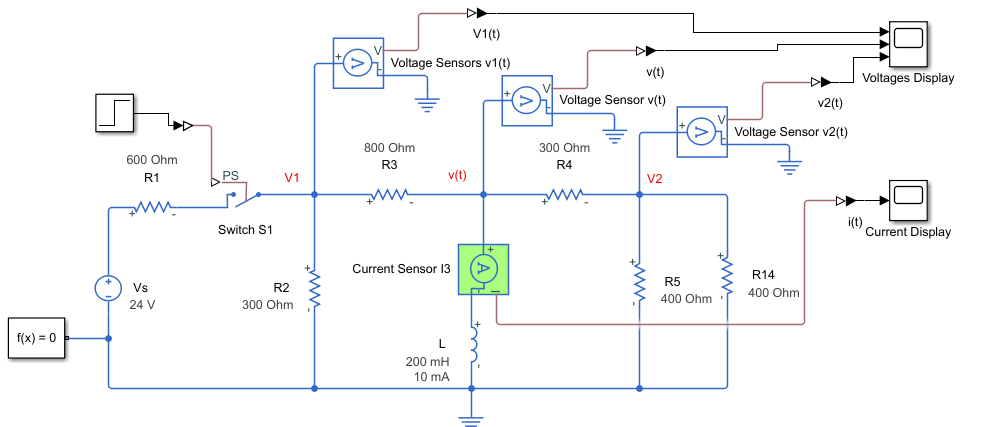

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018